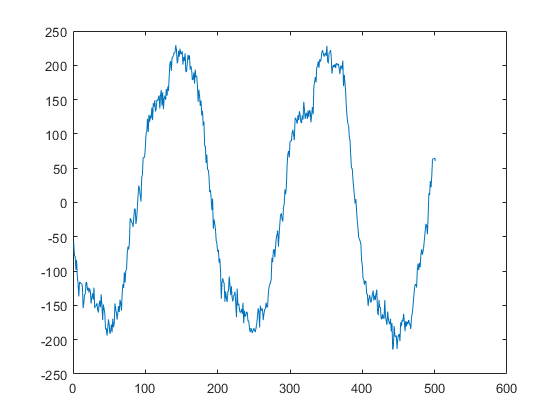

load('C:\Users\dfpsi\sciebo\ProjektSeminar\dataset\subject1\stage2\imgV2.mat');
data = imgV2;

fs = 50;
tStart = 11;
tEnd = 21;

lungPix = [15,13];

lung = squeeze(data(lungPix(1),lungPix(2),(tStart * fs):(tEnd * fs)));
figure; plot(lung);

data = data(:,:,(tStart * fs):(tEnd * fs));

dataFlat = reshape(data,size(data,1) * size(data,2), []);

order = 250;

[d1,p1] = aryule(lung,order);
p1

p1 = 94.0173

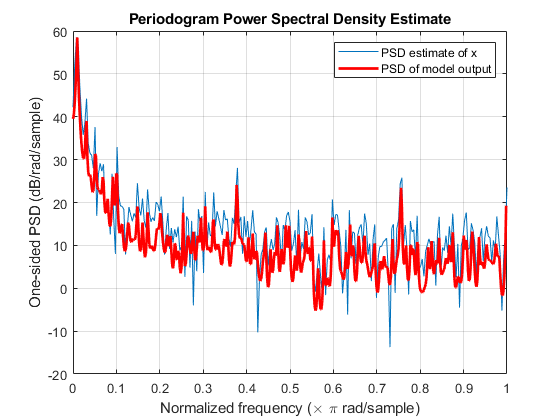


figure;
[H1,w1] = freqz(sqrt(p1),d1);
periodogram(lung)
hold on
hp = plot(w1/pi,20*log10(2*abs(H1)/(2*pi)),'r'); % Scale to make one-sided PSD
hp.LineWidth = 2;
xlabel('Normalized frequency (\times \pi rad/sample)')
ylabel('One-sided PSD (dB/rad/sample)')
legend('PSD estimate of x','PSD of model output')

[d2,p2] = lpc(lung,order);
[d1.',d2.']

ans =     1.0000    1.0000
   -0.7585   -0.7585
   -0.2197   -0.2197
   -0.0096   -0.0096
   -0.0577   -0.0577
   -0.0989   -0.0989
   -0.0394   -0.0394
    0.1203    0.1203
    0.0269    0.0269
    0.0248    0.0248


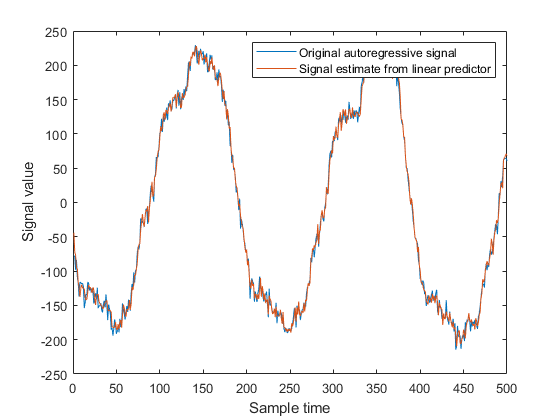

xh = filter(-d2(2:end),1,lung);

figure;
plot([lung(2:end),xh(1:end-1)])
xlabel('Sample time')
ylabel('Signal value')
legend('Original autoregressive signal','Signal estimate from linear predictor')

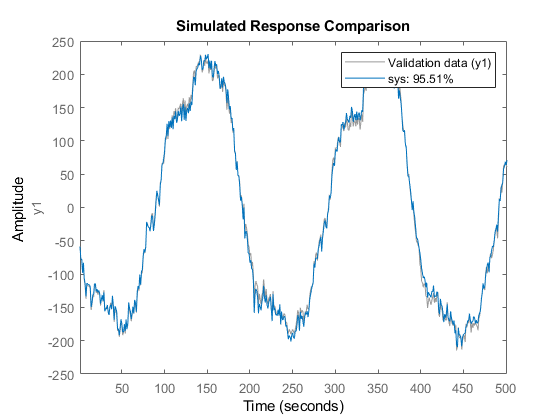

order = 250;
sys = ar(lung, order);

figure; compare(lung,sys);

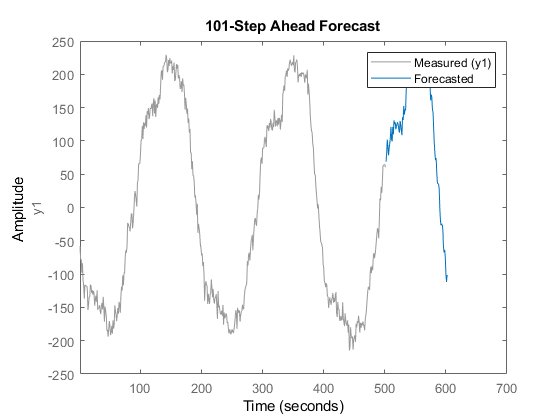

forecast(sys,lung,101);
legend('Measured','Forecasted');

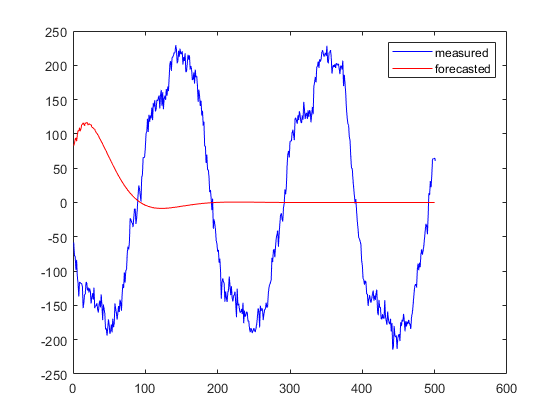


K = 500;
p = forecast(sys,lung,K);

plot(lung,'b'); hold on; 
plot(p,'r'), legend('measured','forecasted')

% Initialize DMD class and properties
dmd = DMD();
rank = -1; % rank to truncate data to
predHor = size(data,3)+1; % prediction horizon (in samples)
t = (0:(size(dataFlat,2)-1))'/fs;
tSim = (1:predHor)'/fs + t(end);

% X = dataFlat(:,1:end-1);
% Y = dataFlat(:,2:end);

X = [dataFlat(:,1:end-5);
     dataFlat(:,2:end-4);
     dataFlat(:,3:end-3);
     dataFlat(:,4:end-2);
     dataFlat(:,5:end-1)];
Y = [dataFlat(:,2:end-4);
     dataFlat(:,3:end-3);
     dataFlat(:,4:end-2);
     dataFlat(:,5:end-1);
     dataFlat(:,6:end)];

% X = [dataFlat(:,1:end-2);
%      dataFlat(:,2:end-1)];
% Y = [dataFlat(:,2:end-1);
%      dataFlat(:,3:end)];

tic
[Ur, Sr, Vr, Atilde] = fitKoopman(dmd, X, Y, rank, predHor);
[lambda, omega, Phi, b] = fitModes(dmd, Ur, Sr, Vr, Atilde, X, Y, 1, 'hankel');
[Xcomps, Xtotal] = reconData(dmd, lambda, omega, Phi, b, predHor, 1, 'disc');
% [lambda, omega, Phi, b, ~] = cleanModes(dmd, lambda, omega, Phi, b);
% [norms, mags, freqs] = interpModes(dmd, lambda, omega, Phi, b);
toc

Elapsed time is 0.048849 seconds.


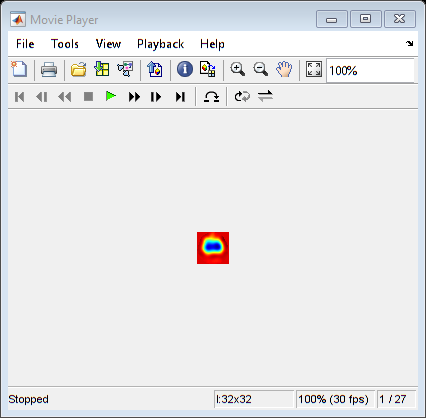

ans =   UnifiedScope with properties:

    InstanceNumber: 13
     Specification: [1×1 iptscopes.IMPlayScopeCfg]
        MessageLog: []
            Visual: [1×1 iptscopes.VideoVisual]
        DataSource: [1×1 matlabshared.scopes.source.WorkspaceSource]
            Parent: [1×1 Figure]



playVideo(reshape(real(Xtotal(1:1024,:)),32,32,[]))

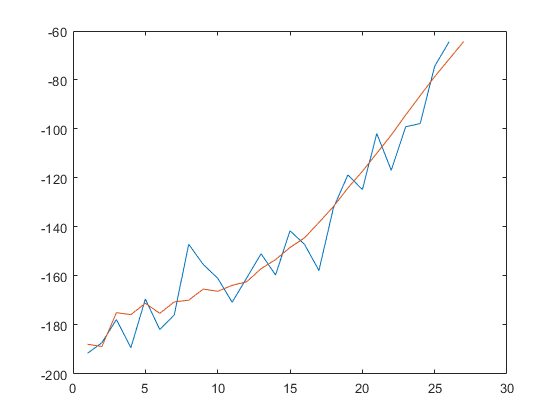

XtotalImg = reshape(real(Xtotal(1:1024,:)),32,32,[]);
lung = squeeze(data(lungPix(1),lungPix(2),:));
lungRecon = squeeze(XtotalImg(lungPix(1),lungPix(2),:));
figure; plot(lung); hold on; plot([lungRecon]);

tic
[PhiGT, omegaGT, lambdaGT, bGT, XdmdGT] = DMDfull(dataFlat, {'r', 72, 'dt', 1, 'nstacks', 1});

Unrecognized function or variable 'dataFlat'.

toc

reconDataGT = reshape(real(XdmdGT),32,32,[]);
playVideo(reshape(reconDataGT,32,32,[]))
lung = squeeze(data(lungPix(1),lungPix(2),:));
lungRecon = squeeze(reconDataGT(lungPix(1),lungPix(2),:));
figure; plot([lung(1:length(lungRecon)),lungRecon]);

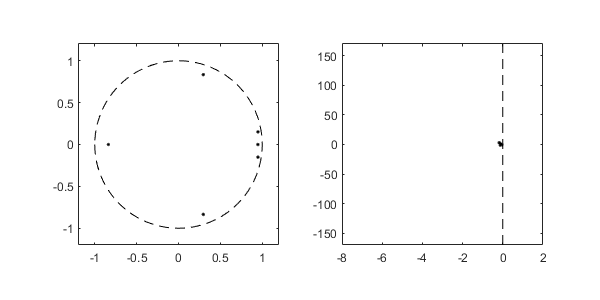

figure('Position', [100 100 600 300]);
subplot(1,2,1);
plot(lambda, 'k.');
rectangle('Position', [-1 -1 2 2], 'Curvature', 1, ...
    'EdgeColor', 'k', 'LineStyle', '--');
axis(1.2*[-1 1 -1 1]);
axis square;


subplot(1,2,2);
plot(omega, 'k.');
line([0 0], 200*[-1 1], 'Color', 'k', 'LineStyle', '--');
axis([-8 2 -170 +170]);
axis square

set(gcf, 'PaperUnits', 'inches', 'PaperPosition', [0 0 6 3], 'PaperPositionMode', 'manual');

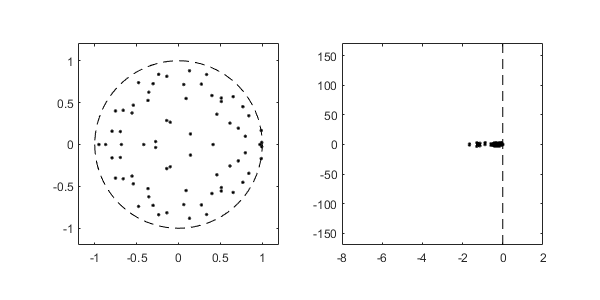

figure('Position', [100 100 600 300]);
subplot(1,2,1);
plot(lambdaGT, 'k.');
rectangle('Position', [-1 -1 2 2], 'Curvature', 1, ...
    'EdgeColor', 'k', 'LineStyle', '--');
axis(1.2*[-1 1 -1 1]);
axis square;


subplot(1,2,2);
plot(omegaGT, 'k.');
line([0 0], 200*[-1 1], 'Color', 'k', 'LineStyle', '--');
axis([-8 2 -170 +170]);
axis square

set(gcf, 'PaperUnits', 'inches', 'PaperPosition', [0 0 6 3], 'PaperPositionMode', 'manual');

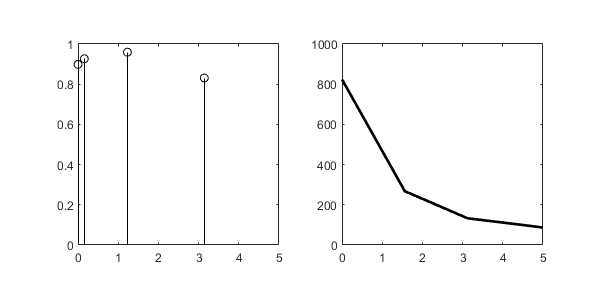

% alternate scaling of DMD modes
f = abs(imag(omega));
P = (diag(Phi'*Phi));

% DMD spectrum
figure('Position', [100 100 600 300]);
subplot(1,2,1);
stem(f, P, 'k');
xlim([0 5]);
axis square;

% power spectrum
timesteps = size(dataFlat, 2);
srate = 50;
nelectrodes = 1024;
NFFT = 2^nextpow2(timesteps);
f = srate/2*linspace(0, 1, NFFT/2+1);

subplot(1,2,2); 
hold on;
[amp,pha,f] = ampPhaseFFT(dataFlat',fs);
plot(f, mean(amp,2),'k', 'LineWidth', 2);
xlim([0 5]);
axis square;
box on;

set(gcf, 'PaperUnits', 'inches', 'PaperPosition', [0 0 6 3], 'PaperPositionMode', 'manual');

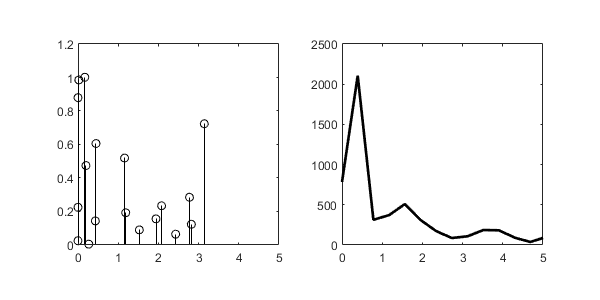

% alternate scaling of DMD modes
f = abs(imag(omegaGT));
P = (diag(PhiGT'*PhiGT));

% DMD spectrum
figure('Position', [100 100 600 300]);
subplot(1,2,1);
stem(f, P, 'k');
xlim([0 5]);
axis square;

% power spectrum
timesteps = size(dataFlat, 2);
srate = 1;
nelectrodes = 1024;
NFFT = 2^nextpow2(timesteps);
f = srate/2*linspace(0, 1, NFFT/2+1);

subplot(1,2,2); 
hold on;
[amp,pha,f] = ampPhaseFFT(dataFlat',fs);
plot(f, mean(amp,2),'k', 'LineWidth', 2);
xlim([0 5]);
axis square;
box on;

set(gcf, 'PaperUnits', 'inches', 'PaperPosition', [0 0 6 3], 'PaperPositionMode', 'manual');

fs = 50;
tStart = 12;
tEnd = 16;

dataFlat = reshape(data,size(data,1) * size(data,2), []);
X = dataFlat(:,1:end-1);
Y = dataFlat(:,2:end);

% Multi-Resolution DMD
% Set desired ranges for frequency, norm (or damping factor), and magnitude
nLevels = 5;
freqLims = [0.1,10];
damLims = [0.9,1];
magLims = [0, 1];

tic
[lambda, omega, Phi, b] = mrFit(dmd, X, Y, 12, nLevels, 100);
% [Xcomps, Xtotal] = reconData(dmd, lambda, omega, Phi, b, predHor, 1, 'cont');
[norms, mags, freqs] = interpModes(dmd, lambda, omega, Phi, b);
[norms, mags, freqs, lambda, omega, Phi, b] = boxSelection(dmd, norms, mags, freqs, ...
                                                                                    lambda, omega, Phi, b, ....
                                                                                    magLims, damLims, freqLims);
[Xcomps, Xtotal] = reconData(dmd, lambda, omega, Phi, b, predHor, 1, 'cont');
toc

Elapsed time is 0.154745 seconds.


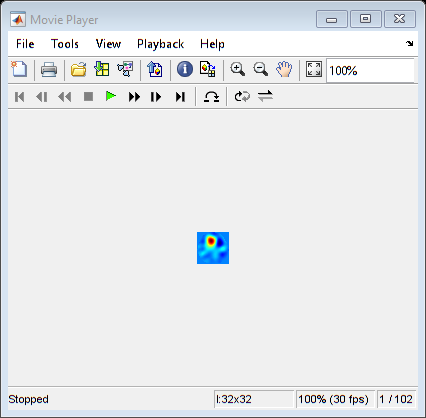

ans =   UnifiedScope with properties:

    InstanceNumber: 1
     Specification: [1×1 iptscopes.IMPlayScopeCfg]
        MessageLog: []
            Visual: [1×1 iptscopes.VideoVisual]
        DataSource: [1×1 matlabshared.scopes.source.WorkspaceSource]
            Parent: [1×1 Figure]


playVideo(reshape(real(Xtotal),32,32,[]))

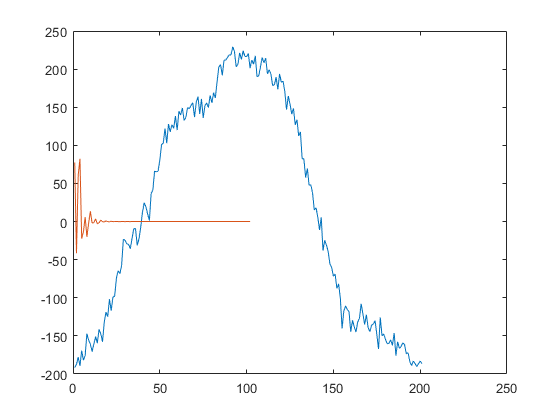

XtotalImg = reshape(real(Xtotal),32,32,[]);
lung = squeeze(data(lungPix(1),lungPix(2),:));
lungRecon = squeeze(XtotalImg(lungPix(1),lungPix(2),:));
figure; plot(lung); hold on; plot([lungRecon]);